syms x
s= tf([1 0],1);
%our transferfunctions
Blank=1; %To clear the control designer app
G=tf([-116.8 0],[1 0.45 -83.11 -2.295]);%Our TF
xG = (-116.8*x)/(x^3+0.45*x^2-83.11*x-2.295);

%Using PID control
%Setting up values
K=[-20 -110 -1.7]; %Gain matrix, kp ki kd

%setting up functions
N=1000;
P = K(1);
I = K(2)/s;
D= K(3)*s;
%D = K(3)*(N/(1+N*(1/s)));
%Setting up functions
PID = P+I+D

PID =
 
  -1.7 s^2 - 20 s - 110
  ---------------------
            s
 
Continuous-time transfer function.



PIDx = K(1) + K(2)/x + K(3)*x;


%Using Ziegel-Nichols algorithm for PID tuning
Ku= 20; %Ultimate gain, to be tuned
Tu= 0.5; %Oscillations time, 
Kzn = [-0.6*Ku -1.2*Ku/Tu -3*Ku*Tu/40] %Algorithm = [0.6*Ku 1.2*Ku/Tu 3*Ku*Tu/40]

Kzn =   -12.0000  -48.0000   -0.7500


%Kzn = [-0.6*Ku -1 -1]

Pzn = Kzn(1);
Izn = Kzn(2)/s;
Dzn= Kzn(3)*s;
PIDzn = Pzn+Izn+Dzn

PIDzn =
 
  -0.75 s^2 - 12 s - 48
  ---------------------
            s
 
Continuous-time transfer function.



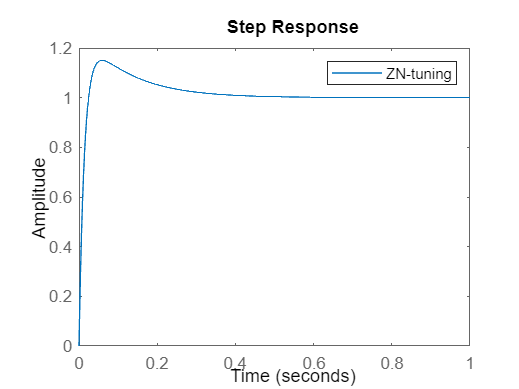


DTzn=series(G,PIDzn);
CLzn=feedback(DTzn,1);
step(CLzn,1), legend('ZN-tuning')

stepinfo(CLzn)

ans = struct with fields:
         RiseTime: 0.0178
    TransientTime: 0.3099
     SettlingTime: 0.3099
      SettlingMin: 0.9142
      SettlingMax: 1.1500
        Overshoot: 14.9548
       Undershoot: 0
             Peak: 1.1500
         PeakTime: 0.0588


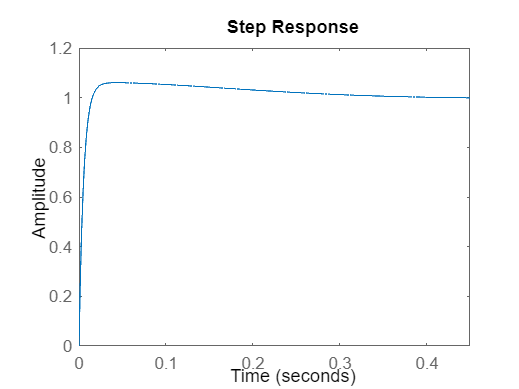

%calculating the steady state error of transferfunction 
%complimented with PID | very good ess-value. 
ess=1/round(abs(limit(PIDx*xG,x,0)));

%Open loop and closed loop
%Making step-response, root locus 
DT=series(G,PID);
CL=feedback(DT,1);
step(CL)

stepinfo(CL)

ans = struct with fields:
         RiseTime: 0.0096
    TransientTime: 0.2527
     SettlingTime: 0.2527
      SettlingMin: 0.9072
      SettlingMax: 1.0603
        Overshoot: 6.0115
       Undershoot: 0
             Peak: 1.0603
         PeakTime: 0.0435


%rlocus(CL)
%nyquistplot(G*PID)
%finding poles and zeores of closed loop
%pole(CL),zero(CL)


%discretisizing PID-controller
BW =bandwidth(CL);  %Bandwidth
Wsamplemin = 20*BW;
Tsmax = 2*pi/Wsamplemin;
dD=c2d(PID,0.005, 'tustin')

dD =
 
  -700.3 z^2 + 1359 z - 660.3
  ---------------------------
            z^2 - 1
 
Sample time: 0.005 seconds
Discrete-time transfer function.



[numerator, denominator]=tfdata(dD,'v'); %poler
